# Internet Speed Test

clc; clear; close all;

## Theoretical values

Enter below the theoretical download  and upload values in Mb/s.

% download theoretical speed
th_download = 100;
% upload theoretical speed
th_upload = 20;

## Dataset name

Enter below the dataset name. The file should contain a single json array.

fname = 'helios-data.json';

## Load data

Load the data into memory.

fid = fopen(fname);
raw = fread(fid,inf);
str = char(raw');
json = jsondecode(str);

## Display data

Display the data structure and the json string.

disp('Loaded data structure:');

Loaded data structure:


disp(json);

  20×1 struct array with fields:

    bytes_sent
    download
    timestamp
    share
    bytes_received
    ping
    upload
    server



disp('Raw json data:');

Raw json data:


disp(str);

[{"bytes_sent": 19603456, "download": 90189120.09819403, "timestamp": "2017-12-12T18:00:02.862936Z", "share": "http://www.speedtest.net/result/6873247579.png", "bytes_received": 112991396, "ping": 18.411, "upload": 15202358.338760694, "server": {"latency": 18.411, "name": "Brussels", "url": "http://speedtest101.proximus.be/speedtest/upload.php", "country": "Belgium", "lon": "4.3500", "cc": "BE", "host": "speedtest101.proximus.be:8080", "sponsor": "Proximus", "lat": "50.8500", "id": "12627", "d": 0.42611459297149684}}
,
{"bytes_sent": 19529728, "download": 90362923.30270956, "timestamp": "2017-12-12T19:00:08.641866Z", "share": "http://www.speedtest.net/result/6873421078.png", "bytes_received": 113073316, "ping": 14.819, "upload": 14617323.988660162, "server": {"latency": 14.819, "name": "Brussels", "url": "http://speedtest101.proximus.be/speedtest/upload.php", "country": "Belgium", "lon": "4.3500", "cc": "BE", "host": "speedtest101.proximus.be:8080", "sponsor": "Proximus", "lat": "50.85

## Extract data

Extract download, upload and timestamp information, and store each of them into a vector. Also, convert the speed into Mb/s.

% number of samples
m = size(json(:),1);

% format and scale downloads & uploads samples
downloads = [json(:).download]' * 1e-6;
uploads = [json(:).upload]' * 1e-6;

% format and convert timestamps to keep only hours
time = zeros(m,1);
for i=1:m
    timestamp = json(i).timestamp;
    [~,~,~,H,MN,~] = datevec(datenum8601(timestamp));
    if MN < 30alberto.sonnino@icloud.com
        time(i) = H;
    else
        time(i) = H+1;
    end
end

## Aggregate data

Aggregate speed for the same hour of the day; compute the mean and standard devisation for each hour.

% download speed
download_aggr = zeros(24,2);
for i=0:23
    tmp = downloads(time==(i));
    download_aggr(i+1,1) = mean(tmp);
    download_aggr(i+1,2) = std(tmp);
end

% upload speed
upload_aggr = zeros(24,2);
for i=0:23
    tmp = uploads(time==(i));
    upload_aggr(i+1,1) = mean(tmp);
    upload_aggr(i+1,2) = std(tmp);
end

## Plot

Plot the aggregated result.

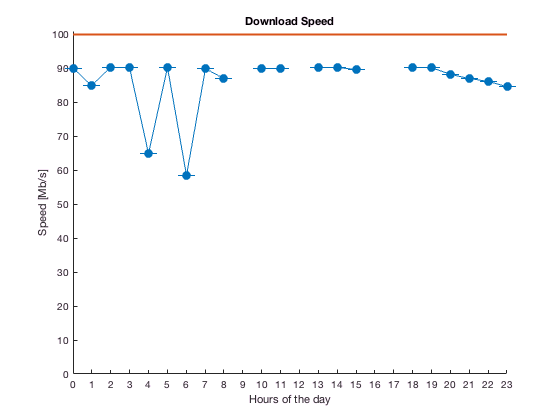

% plot download speed
error_plot(...
    (0:1:23),...
    download_aggr(:,1),...
    download_aggr(:,2),...
    th_download, ...
    'Download Speed'...
);

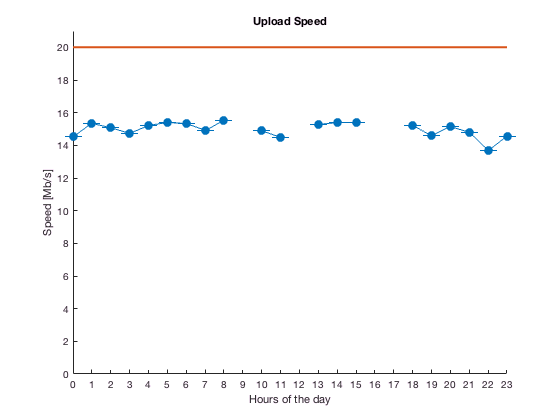


% plot upload speed
error_plot(...
    (0:1:23),...
    upload_aggr(:,1),...
    upload_aggr(:,2),...    
    th_upload,...
    'Upload Speed'...
);